# Plantilla problema práctica 1 Model. Exp.

Es necesario cargar los datos suministrados por la empresa en este punto

load data5

## Petición de la empresa

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 tal y como pueden ver a continuación

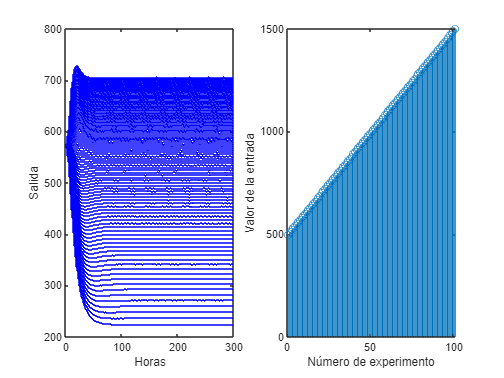

figure(1)
clf
subplot(1,2,1)
stairs(0:300,y_sample','b')
xlabel('Horas')
ylabel('Salida')
subplot(1,2,2)
stem(u_lineal)
xlabel('Número de experimento')
ylabel('Valor de la entrada')

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de 1000 a 1120 de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación

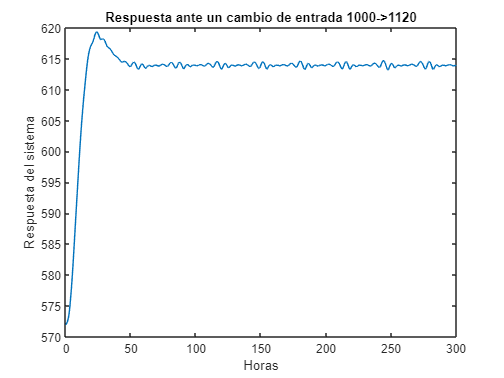

figure(2)
clf
plot(t,y_response)
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

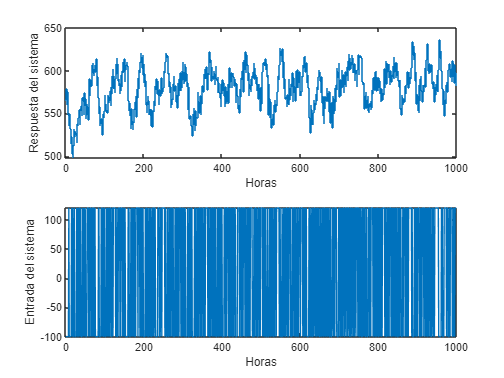

figure(3)
clf
subplot(2,1,1)
stairs(0:1000,y')
xlabel('Horas')
ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000,u)
xlabel('Horas')
ylabel('Entrada del sistema')

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

## Respuesta a la empresa

Cordial Saludo, somos Abelino Sepulveda, Andrés Gómez y Sofia Vega, estudiantes de Ingeniería matemática de la universidad EAFIT, agradecemos la confianza puesta en nosotros para analizar el trabajo que realizó el ingeniero, en el presente informe mostraremos el paso a paso que realizaremos para este análisis.

Como primer paso para la identificación del sistema, debemos evaluar y validar la metodología implementada por el anterior ingeniero. Para esto, calculamos las condiciones experimentales ideales.

#### Paso 1: Rango de Linealidad

Empezamos calculando la curva y rango de linealidad, cuya curva se obtiene con los puntos de equilibrio del sistema a las múltiples entradas con el cual fue excitado. Luego, el rango es obtenido dado que es una aproximación al sistema no lineal y a demás, queremos ver si los valores (entre 900 y 1120) de la señal prbs con la cual fue excitado el modelo se encuentran dentro de este rango.

yss= y_sample(:,250:301);
medias= mean(yss,2);
index_x = find(u_lineal==1000);
valor_y= medias(index_x);
h= u_lineal(2)-u_lineal(1);

- Usando diferencias centradas calculamos el rango de linealidad

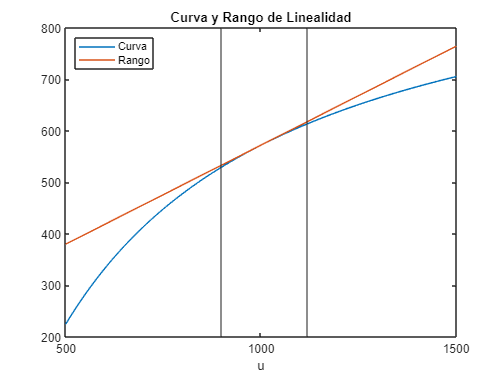

m= (medias(index_x+1)-medias(index_x -1))/(2*h);
syms x
y_rango= valor_y + m*(x-1000);
y_rango= subs(y_rango,x,500:10:1500);
clf 
plot(u_lineal,medias)
title('Curva y Rango de Linealidad')
hold on 
plot(u_lineal,y_rango)
legend('Curva', 'Rango','Location','northwest')
hold on 
xline(1120,'HandleVisibility', 'off')
hold on 
xline(900,'HandleVisibility', 'off')
xlabel('u')

Podemos observar que entre los valores 900 y 1120 hay una buena aproximación lineal. Dado que ambas curvas aún conservan similitud dentro de este rango. Con esto, podemos aprobar los valores de la entrada prbs con la que fue excitada el modelo.

#### Paso 2: Periodo de Muestreo

Dado que se menciona que las muestras del estado del sistema son tomadas en intervalos de una hora. Queremos calcular el mejor periodo de muestreo ya sea por tema de no malgastar recursos o no perder información del sistema / información falsa. Para esto lo calculamos mediante el **teorema de muestreo en la práctica. **Para esto tomamos los datos de "*y_response*", ya que es el sistema excitado con una entrada tipo escalón, así:

$\frac{\textrm{Tr}}{10}\le \textrm{Ts}\le \frac{\textrm{Tr}}{5}$  Donde *Ts* es el Tiempo de Muestreo y *Tr* es el tiempo que tarda el sistema excitado por la entrada escalón de ir al 10% al 90% del punto de estabilidad.

estabilidad_y= mean(y_response(1970:end));
perc_10= y_response(1)+(estabilidad_y-y_response(1))/10;
perc_90= y_response(1)+(estabilidad_y-y_response(1))/10*9;
aux2= find(y_response<=perc_10);
t_10= aux2(end);
aux3=find(y_response<=perc_90);
t_90= aux3(end);
tr= t(t_90)-t(t_10);
ts= [tr/10 tr/5]

ts =     1.0600    2.1200


Podemos ver que el periodo de muestro podría ser de entre 1.06 y 2.12 horas. Observamos que el periodo de muestreo anteriormente comprendido no se encuentra dentro de este intervalo. **Sin embargo, **la diferencia es minúscula/insignificativa. Por lo que también validamos el periodo de muestreo que realizó el anterior Ingeniero.

#### Paso 3: Diseño del Tipo de Entrada

Como siguiente paso, debemos comprobar el diseño de entrada. Idealmente ésta debería tener un factor de cresta bajo y también un orden de excitación persistente alto.

Para calcular el factor de cresta tomamos en consideración la siguiente fórmula: $\frac{\max \left({\left(u-\textrm{medias}\left(u\right)\right)}^2 \right)}{\textrm{var}\left(u\right)}$

aux= zeros(length(u), 1);
for i=1:length(u)
    aux(i) = (u(i)-mean(u))^2;
end
factor_cresta= max(aux)/var(u)

factor_cresta = 1.0050

Y observamos que evidentemente contamos con un factor de cresta alto. Adicional se encuentra que cuenta con un orden de excitación persistente de 50, la cual es alta (mostrado más adelante).

Con esto, podemos finalizar la etapa de validación de procedimientos realizados por el anterior ingeniero. Donde concluimos que lo empleado por el momento había sido de manera correcta. Por consiguiente, decidimos empezar el proceso de identificación del sistema.

Para esto, continuamos con el siguiente paso

**Paso 4: Preprocesamiento de los datos**

Realizamos el preprocesamiento de los datos muestrados, para esto, queremos:

- Remover tendencias

- Quitar Medias

- Remover outliers

Los dos primeros ítems son realizados por el toolbox SystemIdentification que se utilizará más adelante, para satisfacer el tercer item debemos remover los outliers. Para esto, como estamos trabajando con una serie de tiempo, decidimos usar el filtro de hampel el cual funciona por un tipo de "ventana movil" el cual calcula los outliers por medio de la media y desviación de sus vecinos.

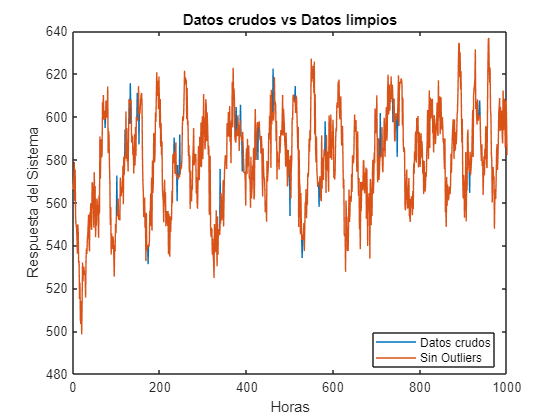

u=u';
clean_d= hampel(y);
clf
plot(0:1:1000,y)
hold on
plot(0:1:1000,clean_d)
xlabel('Horas')
ylabel('Respuesta del Sistema')

title('Datos crudos vs Datos limpios')
legend('Datos crudos','Sin Outliers','Location','best')

data =

Time domain data set with 1001 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 1 output(s), 1001 samples 
and 1 experiment(s).

All inputs in the data have been denoted as 'zero order hold' ('zoh'), i.e. 
they are assumed to be piecewise constant over the sample time.
If the input is a sampled continuous signal and you plan to build or convert to 
continuous-time models, it is recommended to mark the InterSample property as 
'First order hold': Data.InterSample = 'foh' or Data.int = {'foh','foh', ...} 
for multi-input signals.

Some inputs and/or outputs have non-zero means. It is generally recommended to 
remove the means by DAT = DETREND(DAT), except in the following cases:
1. The signals are measured relative to a level that corresponds to a physical 
equilibrium. This could e.g. be the case if step responses are recorded from an 
equilibrium point. In this case, it is advisable to remove the equilibrium 
values rather than data means. You may do so u

En la figura anterior podemos obversar la comparación entre los datos crupos y los datos limpios. Por lo cual ahora sí podemos empezar con el **proceso de identificación**

Para utilizar el toolbox mencionado anteriormente, debemos tener los datos en una estructura especifica, para esto utilizamos la próxima linea de código

data= iddata(y,u) %datos de identificación
advice(data)

ans = 50

Orden de excitación persistente 

pexcit(data)

ans = 4

Retardo entregado por Matlba

delayest(data)

Con esto, podemos ver que el sistema puede tener un retardo cercano a 4. Sin embargo, más adelante será estimado de forma más certera.

Observación de la señal de los datos (**periodograma**)

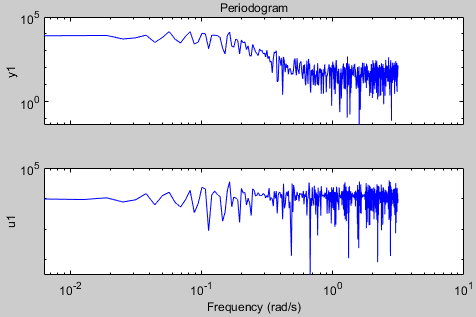

En esta figura, podemos ver la respuesta del sistema ante las frecuencias. Podemos observar también que la entrada y la salida empiezan a comportarse de forma ruidosa al mismo tiempo después de cierto instante. Lo que nos informa que el sistema no está respondiendo de forma efectiva a esas frecuencias por lo que a partir de ese punto deja de ser confiable. Por lo cual **sería recomendable** una señal de entrada con menos frecuencias altas.

Ahora, como primer paso para el proceso de identificación, calculamos un modelo basado en respuesta temporal y otro de frecuencias. Los cuales son estimados a través de métodos no paramétricos. Es bien sabido que estos en general no son buenas aproximaciones del sistema sin embargo, nos ayudan en todo el proceso para validar el sistema.

Observamos la respuesta al impuso del modelo y observamos la secuencia de ponderación:

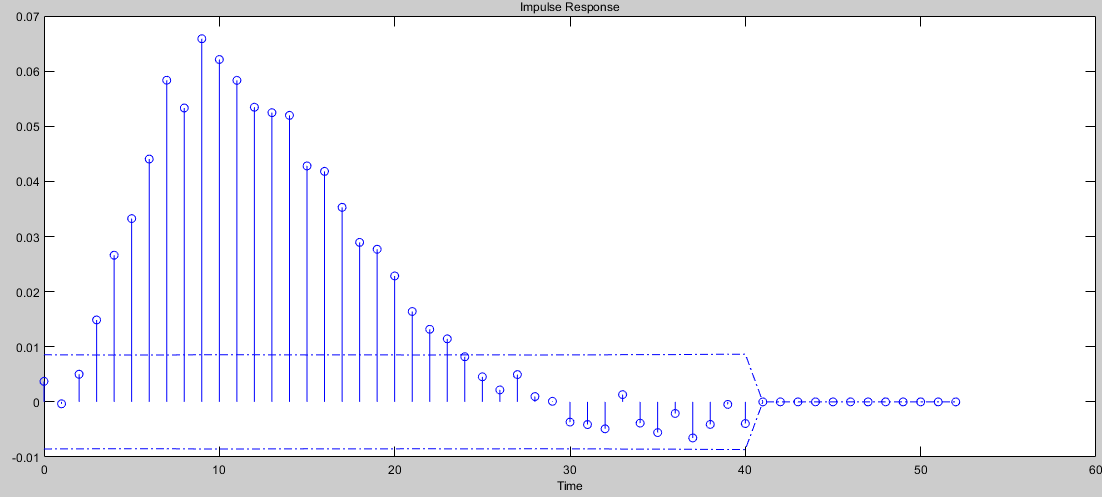 

En la imagen anterior podemos ver que al principio de esta secuencia contamos con **tres ceros significativos **lo cual nos indica que el **retardo del sistema es de 3**. El cual es un valor cercano 4 (el retardo estimado anteriormente). 

Empezamos con el proceso de identificación de modelo. Empezamos con la estructura ARX que es la estructura más sencilla y **además**, porque ésta nos da la noción del orden del modelo.

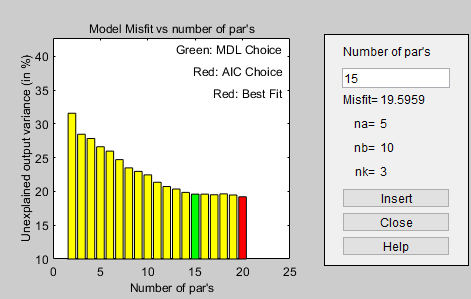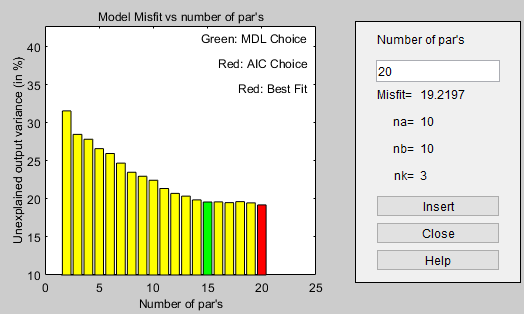

Para esto, se hizo una prueba de na= 1:10, nb=1:10 y nk=3. Con esta figura, observamos que la estructura no es para nada un ARX, sin embargo, se evidencia que más o menos el modelo podría tener un orden variando entre 5 y 10. 

Ahora, con este dato en mente, procedemos con la prueba de otras estructuras cuyos órden estén entre los ya mencionados. 

Después de muchas pruebas entre las variaciones de los órdenes, nuestro equipo encontró tres estructuras de modelos importantes. Los cuales se muestran a continuación:

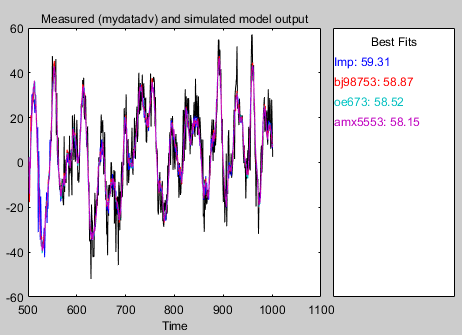

Como habíamos mencionado antes, tomamos el modelo estimado anteriorme por métodos no paramétricos para validar nuestros sistemas. Con esto observamos que encontramos tres estructuras, todas tres con un ajuste muy parecido, es decir, **la diferencia entre ellos no es significativa**. Por lo que decidimos seguir haciendo pruebas unicamente con los dos primeros modelos: **Box Jenkins y OE.**

En este paso, decidimos hacer una prueba de autocorrelación de los modelos y nos encontramos con los siguientes resultados:

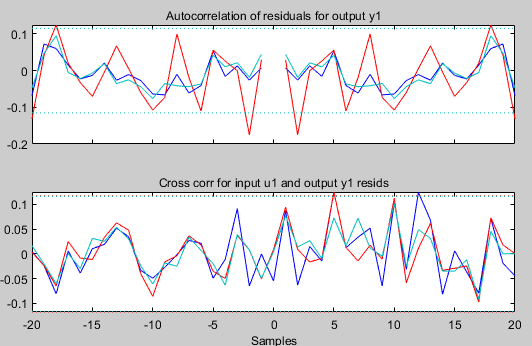

En la figura podemos observar la correlación entre los residuales y la salida (**los cuales no deben estar correlacionados**): donde la linea roja es el modelo Box Jenkins, la cian el OE y la Azul el modelo no paramétrico. Y vamos que es evidente que se encuentre dentro las bandas lo que significa que no hay correlación existente. **SIN EMBARGO, e**stamos viendo que el modelo BJ en la grafica de correlación de los residuales y la salida tiene oscilaciones un poco bruscas y en un punto se salen de la banda. **Adicionalmente **en relación a esto y a un principio muy importante en la ciencia el cual es el **Principio de Parsimonia **el cual nos afirma que en igualdad de condiciones (en este caso el mode BJ y OE tienen un ajuste parecido) la explicación más sencilla suele ser la correcta. Por lo que más adelante dicidimos hacer las prueba con el modelo OE ya que este es un modelo más sencillo y a demás cuenta con un orden más bajo.

Realizamos un análisis de polos y ceros del modelo para ver si se podía reducir el ordel del sistema y nos encontramos con la siguiente gráfica: 

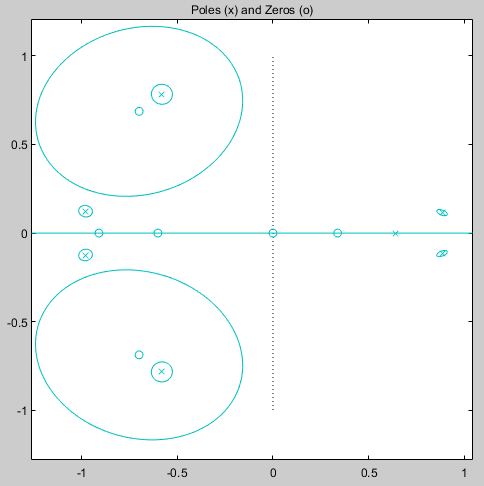

Observamos que puede haber reducibilidad del orden del modelo, por lo que realizamos las respectivas reducciones de orden y quedamos con una estructura **OE 123 **y observando la gráfica del análisis de polos y ceros vemos que el sistema ya es irreducible.

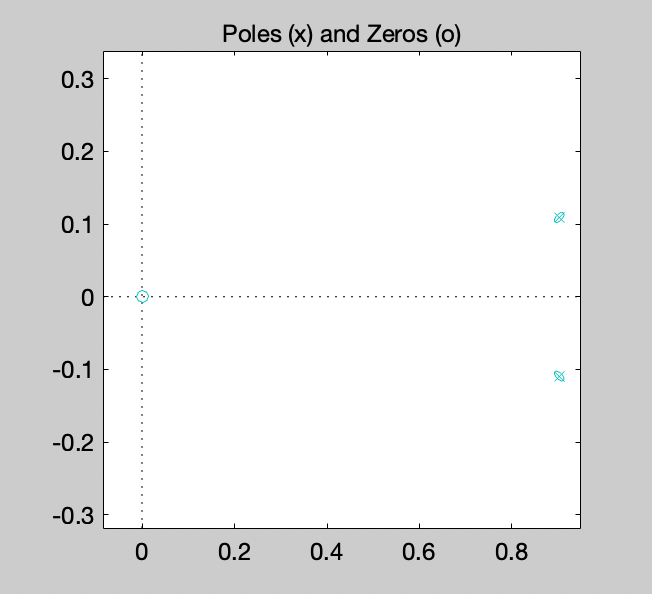

 Con lo que finalmente observamos:

**Ajuste del modelo**

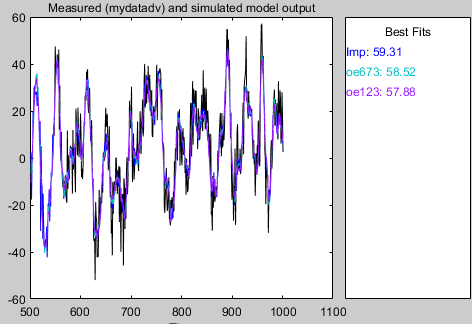

**Análisis de residuales**

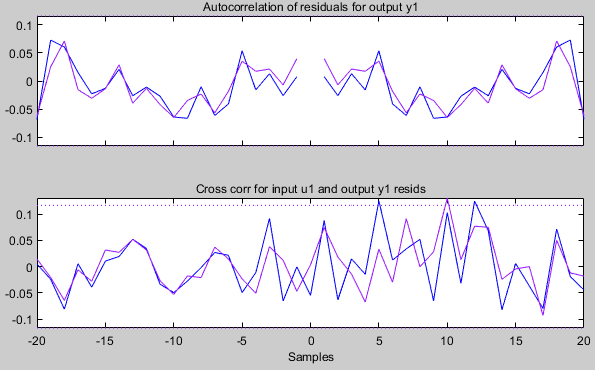

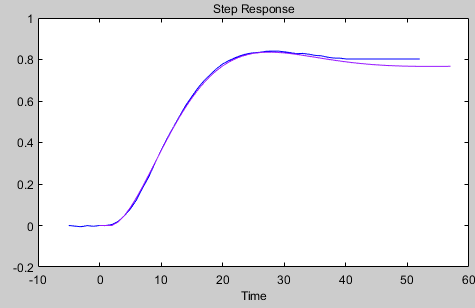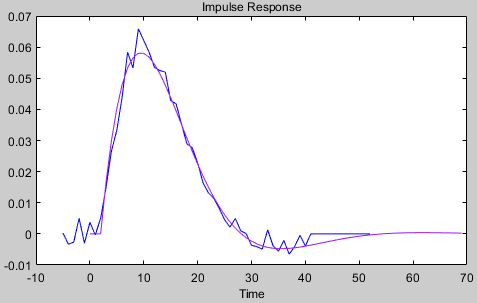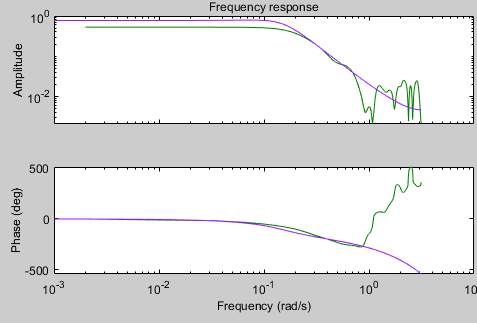

En las figuras anteriores pueden **observar y evaluar **los resultados obtenidos con un modelo **OE123. **En la primera gráfica se observa la comparación del ajuste del modelo antes de reducir los polos y ceros con el sistema irreducible, vemos que no tiene diferencia significativa al haber llegado hasta este sistema reducido. Podemos comparar la correlación de los residuales y la salida (el cual tiene buenos resultados). También la respuesta del sistema ante una entrada tipo escalón y tipo impulso. 

#### Estructura OE 123:


$$\begin{array}{l}
y\left(t\right)=\frac{b_1 q^{-3} +b_2 q^{-4} }{1+a_1 q^{-1} }u\left(t\right)+e\left(t\right)\\
y\left(k\right)=a_1 y\left(k-1\right)+b_1 u\left(k-3\right)+b_2 u\left(k-4\right)+e\left(k\right)+a_1 e\left(k-1\right)\\
G\left(z\right)=\frac{b_1 z+b_2 }{z^3 \left(z+a_1 \right)}
\end{array}$$


### Conclusiones y Recomendaciones

En nuestra labor como ingenieros decidimos **documentar y reportar **todo el procedimiento realizado para el proceso de identificación. Esto con el fin de darles potestad de revisar y cuestionar nuestra metodología. En respuesta a su solicitud concluimos que el modelo del sistema es un OE123, modelo obtenido gracias a su ajuste y con ayuda del principio de parsimonia. Sin embargo es **evidente **que el ajuste de los modelos es muy bajo. Esto puede ser ocasionado por muchas razones. Sin embargo la principal razón creemos que es por error en las mediciones, por lo cual se recomiendar revisar este proceso, sea bien por error en maquinaria o error humano y luego, realizar un remuestreo de los datos.